%% AE 6355 - Individual Project - Mars Tauber-Sutton Validation (Pathfinder)

% Pathfinder is used because its entry velocity (7.48 km/s) is the one
% Mars entry in the NASA Probe Blue Book (Planetary Mission Entry
% Vehicles Quick Reference Guide v4.1) that falls inside Tauber-Sutton's
% valid Mars range (6.5-9 km/s); most Mars landers (Viking, MER,
% Phoenix, MSL, InSight, Mars2020) enter at 4.4-5.8 km/s, too slow for
% this correlation.
%
% Reference (Blue Book): peak convective ~100.69 W/cm^2, peak radiative
% ~5.27 W/cm^2 (with ablation).

clear; clc; close all;

%% -----------------------------------------------------------------
%% MARS CONSTANTS (literature-sourced)
%% -----------------------------------------------------------------
g0_mars   = 3.71;        % m/s^2
Re_mars   = 3389.5e3;    % m
rho0_mars = 0.020;       % kg/m^3
H_mars    = 11.1e3;      % m

%% -----------------------------------------------------------------
%% PATHFINDER ENTRY CONDITIONS (Blue Book, p.16)
%% -----------------------------------------------------------------
V0     = 7480;              % m/s, relative entry velocity
gamma0 = deg2rad(14.06);    % rad, positive-down (sign-flipped from Blue Book's -14.06 deg)
h0     = 130.86e3;          % m, entry interface altitude

rn         = 0.66;          % m, nose radius
beta_const = 61.5;          % kg/m^2, at peak dynamic pressure (Blue Book)
LD_const   = 0;             % ballistic

skip_altitude = h0 + 100;
tspan = [0 2000];
ode_settings = {'RelTol',1e-8, 'AbsTol',[1e-3 1e-10 1e-3], 'MaxStep',0.5};

%% -----------------------------------------------------------------
%% INTEGRATION
%% -----------------------------------------------------------------
params.Re = Re_mars;
params.beta = @(V,h) beta_const;
params.LD   = @(V,h) LD_const;
params.sigma = @(t) 0;
params.g_fun = @(h) g0_mars*(Re_mars/(Re_mars+max(h,0)))^2;
params.rho_fun = @(h) rho0_mars*exp(-max(h,0)/H_mars);

x0 = [V0; gamma0; h0];
opts = odeset(ode_settings{:}, 'Events', @(t,x) ground_skip_event(t,x,skip_altitude));
[t, x, te, xe, ie] = ode45(@(t,x) EOM_3DOF(t, x, params), tspan, x0, opts);

if isempty(ie)
    outcome = 'time limit';
elseif ie(end) == 1
    outcome = 'ground impact';
else
    outcome = 'atmospheric skip-out';
end

V = x(:,1);
h = x(:,3);
fprintf('Outcome: %s at t=%.2f s (V=%.1f m/s, h=%.2f km)\n', outcome, te, xe(1), xe(3)/1000);

Outcome: ground impact at t=234.13 s (V=170.0 m/s, h=-0.00 km)



%% -----------------------------------------------------------------
%% POST-HOC: HEATING
%% -----------------------------------------------------------------
rho_t = rho0_mars*exp(-max(h,0)/H_mars);

% Sutton-Graves convective heating. Derived for Earth air; applying it
% directly to Mars (CO2-dominated) is a known first-order approximation
% common in mission studies, not independently validated for Mars here.
k_SG = 1.7415e-4;
qdot_conv = k_SG*sqrt(rho_t/rn).*V.^3 / 1e4;   % W/cm^2
[qdot_conv_peak, idx_conv_peak] = max(qdot_conv);

% Mars Tauber-Sutton radiative heating (report Eq. 28, Mars
% coefficients). Pathfinder's rn=0.66m falls below the correlation's
% stated 1-23m range; mild extrapolation, same caveat as Earth's rn.
C_M = 2.35e4;
a_M = 0.526;
b_M = 1.19;

V_kms = V/1000;
in_range_TS = V_kms >= 6.5 & V_kms <= 9.0;
qdot_rad = zeros(size(V));
qdot_rad(in_range_TS) = C_M * rn^a_M * rho_t(in_range_TS).^b_M ...
    .* tauber_sutton_fV(V(in_range_TS), 'mars');   % W/cm^2
[qdot_rad_peak, idx_rad_peak] = max(qdot_rad);
Q_rad_total = trapz(t, qdot_rad);

fprintf('\n--- MARS TAUBER-SUTTON VALIDATION (Pathfinder) ---\n');


--- MARS TAUBER-SUTTON VALIDATION (Pathfinder) ---


fprintf('Peak convective (Sutton-Graves): %.2f W/cm^2 at t=%.1f s (V=%.2f km/s)\n', ...
    qdot_conv_peak, t(idx_conv_peak), V(idx_conv_peak)/1000);

Peak convective (Sutton-Graves): 96.72 W/cm^2 at t=57.6 s (V=6.45 km/s)


fprintf('  Reference (Blue Book): ~100.69 W/cm^2\n');

  Reference (Blue Book): ~100.69 W/cm^2


fprintf('Peak radiative (Tauber-Sutton, Mars): %.2f W/cm^2 at t=%.1f s (V=%.2f km/s)\n', ...
    qdot_rad_peak, t(idx_rad_peak), V(idx_rad_peak)/1000);

Peak radiative (Tauber-Sutton, Mars): 4.31 W/cm^2 at t=53.2 s (V=6.81 km/s)


fprintf('  Reference (Blue Book, with ablation): ~5.27 W/cm^2\n');

  Reference (Blue Book, with ablation): ~5.27 W/cm^2


fprintf('Integrated radiative heat load: %.2f J/cm^2\n', Q_rad_total);

Integrated radiative heat load: 66.15 J/cm^2


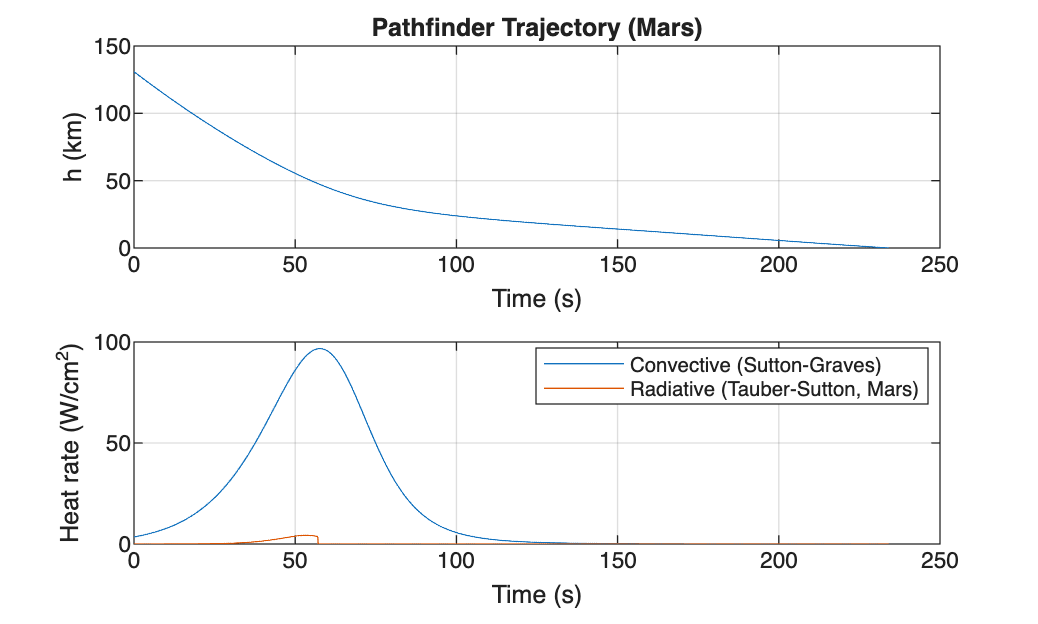


figure;
subplot(2,1,1);
plot(t, h/1000); xlabel('Time (s)'); ylabel('h (km)'); grid on;
title('Pathfinder Trajectory (Mars)');
subplot(2,1,2);
plot(t, qdot_conv, t, qdot_rad);
legend('Convective (Sutton-Graves)', 'Radiative (Tauber-Sutton, Mars)', 'Location','best');
xlabel('Time (s)'); ylabel('Heat rate (W/cm^2)'); grid on;


%% ===================================================================
%% LOCAL FUNCTIONS
%% ===================================================================

function [value, isterminal, direction] = ground_skip_event(t, x, skip_altitude)
    h = x(3);
    value      = [h; h - skip_altitude];
    isterminal = [1; 1];
    direction  = [-1; +1];
end

function xdot = EOM_3DOF(t, x, params)
    V     = x(1);
    gamma = x(2);
    h     = x(3);

    if V <= 0
        error('Nonpositive velocity at t=%.6f s.', t);
    end

    h_env = max(h, 0);
    Re    = params.Re;
    beta  = params.beta(V, h_env);
    LD    = params.LD(V, h_env);
    sigma = params.sigma(t);
    g     = params.g_fun(h_env);
    rho   = params.rho_fun(h_env);

    dVdt     = -rho*V^2/(2*beta) + g*sin(gamma);
    dgammadt = -V*cos(gamma)/(Re + h) - (rho*V/(2*beta))*LD*cos(sigma) + g*cos(gamma)/V;
    dhdt     = -V*sin(gamma);

    xdot = [dVdt; dgammadt; dhdt];
end

function fV = tauber_sutton_fV(V, planet)
% Tabulated Tauber-Sutton f(V), Table 1 (Tauber & Sutton, 1991), V in
% m/s. Log-space pchip interpolation.
    switch planet
        case 'earth'
            V_table = [9000,9250,9500,9750,10000,10250,10500,10750,11000, ...
                       11500,12000,12500,13000,13500,14000,14500,15000,15500,16000];
            fV_table = [1.5,4.3,9.7,19.5,35,55,81,115,151,238,359,495,660,850,1065,1313,1550,1780,2040];
        case 'mars'
            V_table = [6000,6150,6300,6500,6700,6900,7000,7200,7400,7600,7800,8000,8200,8400,8600,8800,9000];
            fV_table = [0.2,1.0,1.95,3.42,5.1,7.1,8.1,10.2,12.5,14.8,17.1,19.2,21.4,24.1,26.0,28.9,32.8];
        otherwise
            error('Unknown planet for tauber_sutton_fV: %s', planet);
    end

    fV = exp(interp1(V_table, log(fV_table), V, 'pchip', 'extrap'));
end